% Calculates DNL and INL for Monte Carlo simulations.
% transistor sizing: 24x8
% circuit parameters
% Vout = 0.6V
% Input current into ladder network = ~7.02uA

LSB =               5.484375e-08


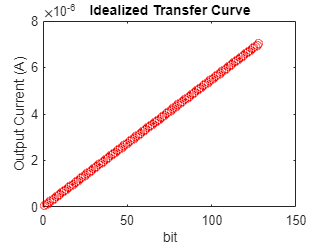

%input variables:
data_name = 'new_24_8_'; %mc data name

%read in mc data
output_currents = []; %create empty list for appending output currents per run
for run = 1:10
    format longg %increase precision
    data = readmatrix(['/data/' data_name num2str(run)]);
    output_currents(:,run) = data(:,9);
end

%idealized transfer curve:
%input current into ladder network
max_currents = max(output_currents); %max current per run
max_current = max(max_currents); %max current of all runs
LSB = max_current / 128 %7 bit resolution

LSB =        5.4756146484375e-08


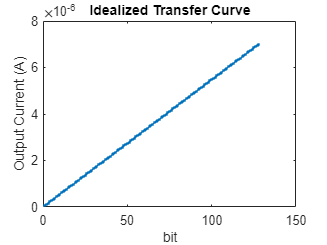

x = linspace(1,128,128);
y = LSB * x;

clf
figure
plot(x, y,'.-')
hold on
title("Idealized Transfer Curve")
xlabel('bit')
ylabel('Output Current (A)')
hold off

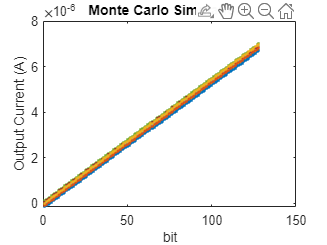

%create mc plot
clf
figure
plot([1:128],output_currents,".-")
hold on
title("Monte Carlo Simulations")
xlabel('bit')
ylabel('Output Current (A)')
hold off

%Calculate DNL and INL of mc simulations
DNLs = [];
INLs = [];

%DNL calculation
for run = 1:10
    Iref = max_currents(run); %per run
    LSB = Iref/128;
    DNL = diff(output_currents(:,run))/LSB-1;
    DNLs(:,run) = DNL;
end

%show worst DNLs
DNLs_worst = max(DNLs)

DNLs_worst =          0.139498770121584        0.0904933040491374         0.102313990497568        0.0933408770162227        0.0468766098497717         0.124245477096346        0.0864034294485794         0.256709256528953         0.158863561272612         0.154866667955897



%INL calculation
for run = 1:10
    INL = sum(DNLs(:,run));
    INLs(:,run) = INL;
end

%show INLs
INLs

INLs =           2.36805958088165         0.595661503307239          3.04563197427951         0.958386773750828        -0.987120040141041          1.58326259347311         0.113077373818041          4.08100430044998          2.84467274202972         0.883285303506689
